addpath('C:\Users\prakh\Documents\MATLAB\saved');
rng('default');
% -------------------------------------------------------------------------
% 1. Define anchor positions and target position
% -------------------------------------------------------------------------
anchorpos2D = [5.7093 4.0633 2.6803; % Anchor positions (x-coordinates)
               4.9640 0.9443 0.2684]; % Anchor positions (y-coordinates)

tgtpos2D = [2.2966; -2.4799;]; % Target position [x; y]

% -------------------------------------------------------------------------
% 2. Calculate distances and RSSI with Rayleigh fading
% -------------------------------------------------------------------------
% Transmitter/Receiver parameters
txPower = 30; % Tx power [dBm]
txGain = 15;  % Tx antenna gain [dBi]
rxGain = 10;  % Rx antenna gain [dBi]
systemLoss = 0; % System loss [dB]
fGHz = 3.5;
fHz = 3.5 * 1e9;
c = physconst('LightSpeed');       % Speed of light [m/s]
pi = 3.14;

% Initialize distances, RSSI, and estimated distances arrays
numAnchors = size(anchorpos2D, 2);
distances = zeros(numAnchors, 1);
rssis = zeros(numAnchors, 1);
rssisRayleigh = zeros(numAnchors, 1); % RSSI with Rayleigh fading
estimatedDistances = zeros(numAnchors, 1);

% Loop through each anchor
for i = 1:numAnchors
    % Calculate Euclidean distance between the target and each anchor
    distances(i) = sqrt((anchorpos2D(1, i) - tgtpos2D(1))^2 + (anchorpos2D(2, i) - tgtpos2D(2))^2);

    % Calculate path loss using Free-Space Path Loss (FSPL) model
    pathLoss_dB = 20 * log10(distances(i)) + 20 * log10(fHz) - 20 * log10(c) + 20 * log10(4 * pi);

    % Calculate RSSI without fading
    rssis(i) = txPower + txGain + rxGain - pathLoss_dB - systemLoss;

    % Apply Rayleigh fading
    h = (1/sqrt(2)) * (randn() + 1j*randn()); % Rayleigh fading coefficient
    rayleighPower_dB = 10 * log10(abs(h)^2); % Convert fading power to dB
    rssisRayleigh(i) = rssis(i) + rayleighPower_dB; % Apply fading to RSSI

    % Estimate distance using RSSI with Rayleigh fading
    pathLossMeasured_dB = txPower + txGain + rxGain - rssisRayleigh(i) - systemLoss;
    estimatedDistances(i) = 10^((pathLossMeasured_dB - 20 * log10(fHz) + 20 * log10(c) - 20 * log10(4 * pi)) / 20);
end

% -------------------------------------------------------------------------
% 3. Display and visualize results
% -------------------------------------------------------------------------
disp('Anchor Distances (m):');

Anchor Distances (m):


disp(distances);

    8.1889
    3.8531
    2.7750



disp('RSSI without fading (dBm):');

RSSI without fading (dBm):


disp(rssis);

   -6.5893
   -0.0409
    2.8101



disp('RSSI with Rayleigh fading (dBm):');

RSSI with Rayleigh fading (dBm):


disp(rssisRayleigh);

   -3.9740
    4.6171
    2.3806



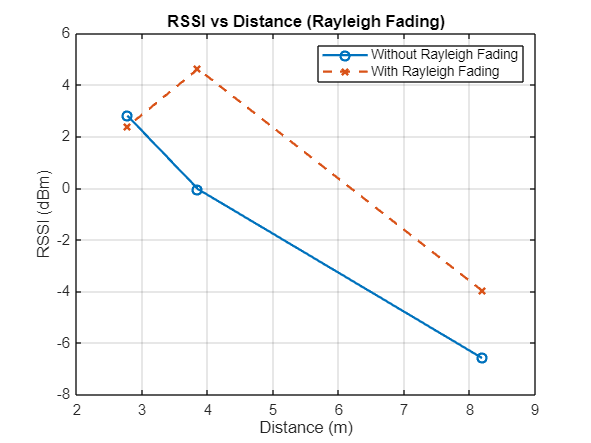


% Plot RSSI vs Distance
figure;
plot(distances, rssis, '-o', 'LineWidth', 1.5); hold on;
plot(distances, rssisRayleigh, '--x', 'LineWidth', 1.5);
xlabel('Distance (m)');
ylabel('RSSI (dBm)');
legend('Without Rayleigh Fading', 'With Rayleigh Fading');
title('RSSI vs Distance (Rayleigh Fading)');
grid on;

estimated_ranges = estimatedDistances'

estimated_ranges =     6.0599    2.2538    2.9156


Initial position estimate using least squares:
    5.5097
   -1.2370

RMSE for estimated position: 
    2.4360

Intersection area between Anchor 1 and Anchor 2: 14.66 m^2
Intersection area between Anchor 1 and Anchor 3: 14.69 m^2
Intersection area between Anchor 2 and Anchor 3: 12.71 m^2
Common Intersection Area for 3 Anchors: 11.42 m^2


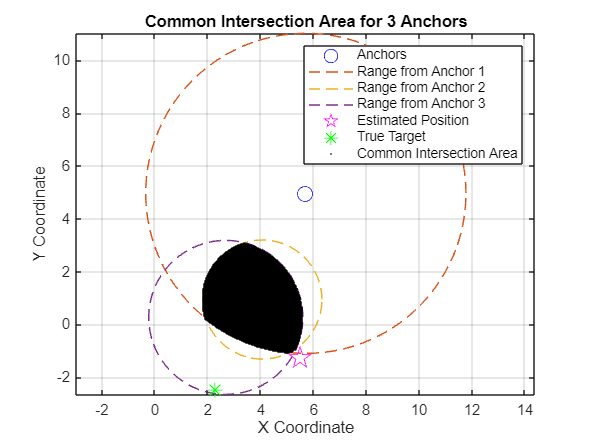


% position estimation using LS
[initial_estimate, rmse, intersection_areas] = estimatePositionUsingLS(anchorpos2D, estimated_ranges, tgtpos2D);

RMSE at Iteration 1: 2.3112
RMSE at Iteration 2: 2.3178
RMSE at Iteration 3: 2.3176
RMSE at Iteration 4: 2.3176
Converged after 4 iterations


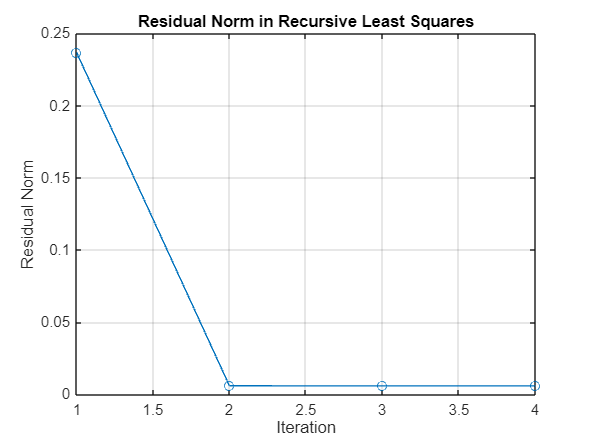

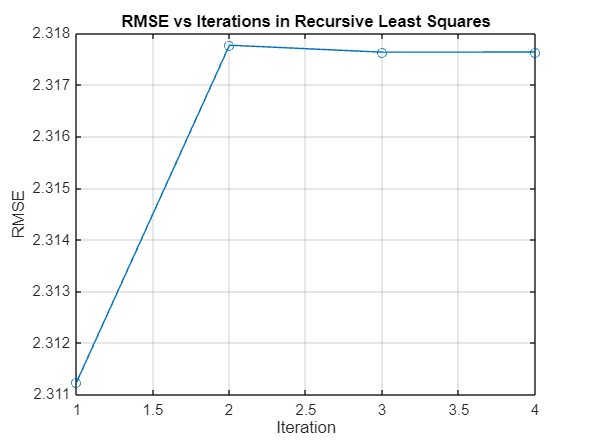


% RLS
[mu_rls, rmse_rls, resnorm_values, rmse_values] = recursiveLeastSquares(anchorpos2D, estimated_ranges, tgtpos2D, initial_estimate);


disp('Final Recursive LS Position:');

Final Recursive LS Position:


disp(mu_rls);

    5.2430
   -1.0441




disp('Final RMSE after Recursive LS:');

Final RMSE after Recursive LS:


disp(rmse_rls);

    2.3176



close(siteviewer);
viewer = siteviewer('Basemap', 'bluegreen');  

weatherpm = propagationModel("gas") + propagationModel("rain");
pm        = propagationModel('longley-rice') + weatherpm;

% Define Parameters
transmitterPower = 40;  % Power in Watts
frequency = 3.5e9;     % Frequency in Hz (3.5 GHz)
antennaHeightTx = 30;  % Tx antenna height in meters
antennaHeightRx = 6;   % Rx antenna height in meters
anchorpos2D_zeroZAxis = [anchorpos2D; 0 0 0];
tgtpos2D_zeroZAxis = [tgtpos2D; 0];

% Define Tx sites without AntennaAngle for isotropic antennas
txs = txsite.empty;  % Pre-allocate an array of txsites
coordsys = "geographic"

coordsys = "geographic"

for i = 1:numAnchors
    txs(i) = txsite(coordsys, ...
        "Name",              sprintf("Tx%d", i), ...
        "AntennaPosition",   anchorpos2D_zeroZAxis(:, i), ...
        "TransmitterPower",  transmitterPower, ...
        "TransmitterFrequency", frequency, ...
        "AntennaHeight",     antennaHeightTx, ...
        "Antenna",           "isotropic");
end

% Show all Tx sites in the viewer
show(txs);

% Print a summary of each Tx to confirm distinct coordinates
disp("Tx Site Properties:");

Tx Site Properties:


for i = 1:length(txs)
    fprintf("\nTx %d:\n", i);
    disp(txs(i));  % Summarizes all key properties
    disp("AntennaPosition: "); 
    disp(txs(i).AntennaPosition);
end


Tx 1:


  txsite with properties:

                    Name: 'Tx1'
        CoordinateSystem: 'geographic'
                Latitude: 42.3001
               Longitude: -71.3504
                 Antenna: 'isotropic'
            AntennaAngle: 0
           AntennaHeight: 30
              SystemLoss: 0
    TransmitterFrequency: 3.5000e+09
        TransmitterPower: 40



AntennaPosition: 


    5.7093
    4.9640
         0




Tx 2:


  txsite with properties:

                    Name: 'Tx2'
        CoordinateSystem: 'geographic'
                Latitude: 42.3001
               Longitude: -71.3504
                 Antenna: 'isotropic'
            AntennaAngle: 0
           AntennaHeight: 30
              SystemLoss: 0
    TransmitterFrequency: 3.5000e+09
        TransmitterPower: 40



AntennaPosition: 


    4.0633
    0.9443
         0




Tx 3:


  txsite with properties:

                    Name: 'Tx3'
        CoordinateSystem: 'geographic'
                Latitude: 42.3001
               Longitude: -71.3504
                 Antenna: 'isotropic'
            AntennaAngle: 0
           AntennaHeight: 30
              SystemLoss: 0
    TransmitterFrequency: 3.5000e+09
        TransmitterPower: 40



AntennaPosition: 


    2.6803
    0.2684
         0




% Define Rx site
rx = rxsite(coordsys, ...
    "Name",             "Target", ...
    "Antenna",          "isotropic", ...
    "AntennaHeight",    antennaHeightRx, ...
    "AntennaPosition",  tgtpos2D_zeroZAxis);
disp(rx);

  rxsite with properties:

                   Name: 'Target'
       CoordinateSystem: 'geographic'
               Latitude: 42.3021
              Longitude: -71.3764
                Antenna: 'isotropic'
           AntennaAngle: 0
          AntennaHeight: 6
             SystemLoss: 0
    ReceiverSensitivity: -100



disp(rx.AntennaPosition);

    2.2966
   -2.4799
         0



show(rx);

% Check LoS and compute coverage
for i = 1:length(txs)
    los(txs(i), rx);   % Draw line-of-sight
    pattern(txs(i));   % Show antenna pattern
end

% Compute coverage for all Tx sites
disp("Calculating coverage for all Tx sites...");

Calculating coverage for all Tx sites...


coverage(txs, ...
              'PropagationModel',      pm, ...
              'ReceiverGain',          rxGain, ...
              'ReceiverAntennaHeight', antennaHeightRx, ...
              'SignalStrengths',       -100:5:-40, ...
              'MaxRange',              1000);